# Exponencial de matriz

Crie uma matriz $A_c$(2 x 2)

Ac = [1 2;3 4]

Ac =      1     2
     3     4


Ac_1 = [0 1; 2 1]

Ac_1 =      0     1
     2     1


Ac_2 = [0 1; -1 -2]

Ac_2 =      0     1
    -1    -2


Obtenha $e^{A_c}$ empregando a função `expm`

expm(Ac)

ans =    51.9690   74.7366
  112.1048  164.0738


expm(Ac_1)

ans =     2.7083    2.3404
    4.6808    5.0487


expm(Ac_2)

ans =     0.7358    0.3679
   -0.3679    0.0000


Compare esse resultado com o obtido ao se empregar os **cinco **primeiros termos da expansão de $e^{A_c}$ em série de potências

N = 5; % Número de termos a serem empregados
aux = eye(2); % Primeiro termo: Identidade
for i = 1:N-1 % (N-1) termos subsequentes
   aux = aux + (Ac^i)/factorial(i);
end
expAc_aproximada = aux

expAc_aproximada =    19.9583   28.0833
   42.1250   62.0833


Experimente aumentar o valor de N no código acima e verifique que o resultado se aproxima do obtido com o uso da função `expm` 

Verifique a propriedade $e^{A_c(t - t_0)} = e^{A_c t} e^{-A_c t_0}$ em um exemplo numérico

t0 = 2; t = 5;
expm(Ac*(t-t0))

ans = 	1.0e+06 *

    2.3858    3.4772
    5.2158    7.6016


expm(Ac*t)*expm(-Ac*t0)

ans = 	1.0e+06 *

    2.3858    3.4772
    5.2158    7.6016


Determine se a matriz $A_c$ é ou não é **Hurwitz**

eig(Ac)

ans =    -0.3723
    5.3723


disp('Como um dos autovalores de Ac está à direita do eixo imaginário, a matriz Ac não é Hurwitz.')

Como um dos autovalores de Ac está à direita do eixo imaginário, a matriz Ac não é Hurwitz.


Faça um gráfico mostrando a evolução dos elementos de $e^{A_ct}$ para $t$ variando de 0 a 1 com passo de 0,01

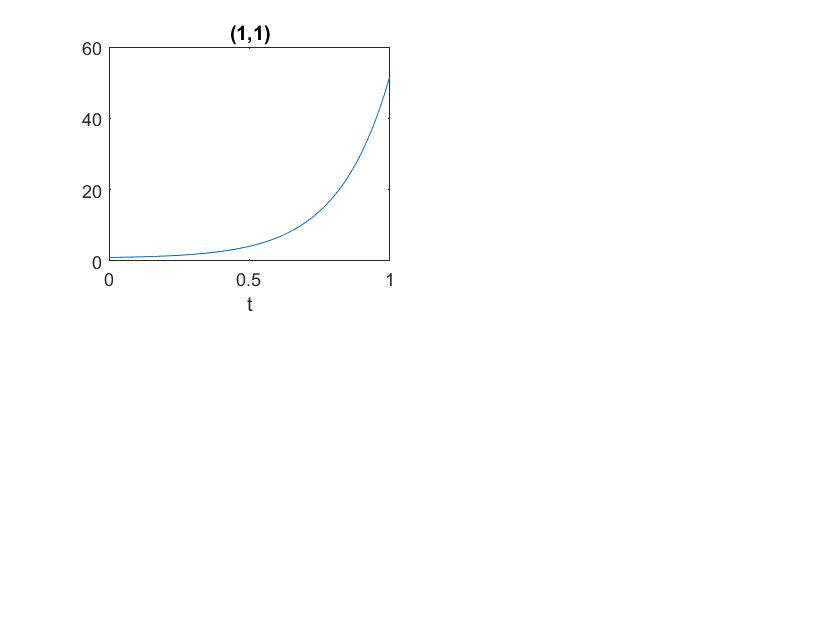

Unrecognized property 'TitleHorizontalAlignment' for class 'matlab.graphics.axis.Axes'.

t = 0:0.01:1;
nt = length(t);
for i = 1:nt
    expAct = expm(Ac*t(i));
    expAct11(i) = expAct(1,1); 
    expAct12(i) = expAct(1,2);                                         
    expAct21(i) = expAct(2,1);
    expAct22(i) = expAct(2,2);
end
subplot(2,2,1),plot(t,expAct11), xlabel('t'),title('(1,1)'), ax = gca; ax.TitleHorizontalAlignment = 'left';

subplot(2,2,2),plot(t,expAct12), xlabel('t'),title('(1,2)'), ax = gca; ax.TitleHorizontalAlignment = 'left';
subplot(2,2,3),plot(t,expAct21), xlabel('t'),title('(2,1)'), ax = gca; ax.TitleHorizontalAlignment = 'left';
subplot(2,2,4),plot(t,expAct22), xlabel('t'),title('(2,2)'), ax = gca; ax.TitleHorizontalAlignment = 'left';

Execute novamente os dois trechos de código acima empregando esta nova matriz:

Ac = [-10 2; 3 -7]

eig(Ac)
disp('Como os dois autovalores de Ac estão à esquerda do eixo imaginário, a matriz Ac é Hurwitz.')
t = 0:0.01:1;
nt = length(t);
for i = 1:nt
    expAct = expm(Ac*t(i));
    expAct11(i) = expAct(1,1); 
    expAct12(i) = expAct(1,2);
    expAct21(i) = expAct(2,1);
    expAct22(i) = expAct(2,2);
end
subplot(2,2,1),plot(t,expAct11), xlabel('t'),title('(1,1)'), ax = gca; ax.TitleHorizontalAlignment = 'left';
subplot(2,2,2),plot(t,expAct12), xlabel('t'),title('(1,2)'), ax = gca; ax.TitleHorizontalAlignment = 'left';
subplot(2,2,3),plot(t,expAct21), xlabel('t'),title('(2,1)'), ax = gca; ax.TitleHorizontalAlignment = 'left';
subplot(2,2,4),plot(t,expAct22), xlabel('t'),title('(2,2)'), ax = gca; ax.TitleHorizontalAlignment = 'left';

Note que os elementos de $e^{A_ct}$ agora **convergem para zero** com o aumento de $t$